clear all; clc
%Defining constants
Ea = 13.4E10; %elastic modulus ceramic
Em = 200E9; %[MPa]; %elastic modulus steel

rho_s = 7.8E3; %kg/m^3
rho_a = 7.7E3; %kg/m^3
U0 = 3.3E-6; %m
ha0 = 2E-3; %m
Fout = 1100; %Newton

x_max = 11E-6; %m

%Variables
tp = 10E-3; %Thickness plate
ts = 10E-3; %thickness spring
margin = 1E-3; %space between spring and actuator

hp0 = 4; %starting height plate
hp1 = 20;%final height plate
hpstep = .1;
hp = [hp0:hpstep:hp1]*1E-3;
L1 = length(hp);

ws0 = 4; %width springs
ws1 = 50;
wsstep = .1;
ws = [ws0:wsstep:ws1]*1E-3;
L2 = length(ws);

Cs = zeros(L1,L2); Cp = zeros(L1,L2); Csys = zeros(L1,L2); Ctot = zeros(L1,L2); Sout = zeros(L1,L2); mtot = zeros(L1,L2);specCtot = zeros(L1,L2); specCsys = zeros(L1,L2);
isValid = zeros(L1,L2);


h0 = 4;
h1 = 50;
hastep = 0.1;
ha = [h0:hastep:h1]*1E-3;
L3 = length(ha)

L3 = 461

was = [7 10]*1E-3;
for l=1:2
    wa = was(l);
    for k = 1:L3
        ca = wa^2 *Ea/ha(k); %stiffnes actuator
        ma = wa * ha(k) * rho_a; %mass actuator
        umax = U0*(ha(k)/ha0-1);
        for i=1:L1 %itterable hp
            for j=1:L2 %itterable ws
                %Computing dimensions
                L = wa + 2 * ws(j) + 2*margin;
                Ip = hp(i)^3 * tp / 12;
                %stiffness
                Cs(i,j) = ws(j)*ts*Em/ha(k);
                Cp(i,j) = 48 * Em * Ip / L^3;
                
                Csys(i,j) = 2*(1/Cp(i,j)+1/Cs(i,j))^-1;
                Ctot(i,j) = (1/(2*Cp(i,j)) + 1/(ca+2*Cs(i,j)))^-1;
                
                
                %output stroke
                Sout(i,j) = (ca*umax + Fout)/(ca+Csys(i,j))*1E6;
                isValid(i,j) = Sout(i,j) >= 11;
                
                %mass
                ms = ws(j)*ha(k)*ts*rho_s;
                mp = L*hp(i)*tp*rho_s;
                mtot(i,j) = 2*ms + 2*mp + ma;
            end
        end
        validCtot = Ctot.*isValid;
        maxCtot(k,l) = max(max(validCtot));
    end
end


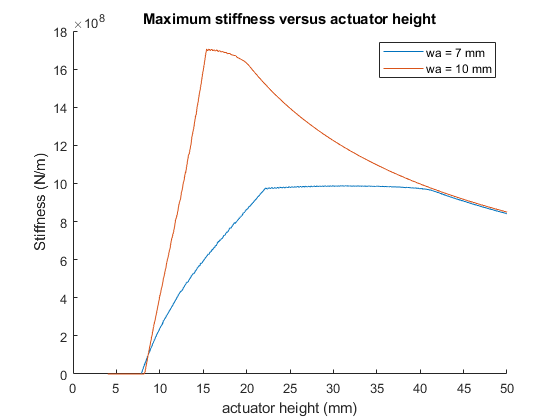


figure 
hold on
hamm =[h0:hastep:h1];
plot(hamm,maxCtot(:,1))
plot(hamm,maxCtot(:,2))
legend('wa = 7 mm','wa = 10 mm')
xlabel('actuator height (mm)')
ylabel("Stiffness (N/m)")
title('Maximum stiffness versus actuator height')
saveas(gcf,'ssa12/height-stiff.png')